# Atividade 09_02

Otávio Baziewicz Filho - 1942808

clc; clear; close all;

## Morfologia matemática (dilatação, erosão, fechamento, abertura, funções strel, imdilate, imerode, imopen, imclose)

Utilizar operações morfológicas para melhorar os resultados da segmentação automática por Otsu das lesões de pele das imagens psl1_gray.png, psl2_gray.png e psl3_gray.png, que você obteve no exercício anterior. A sua solução deve ser uma única, para as três imagens.

**IMPORTANTE: objeto é pixel ‘1’ (branco) e fundo pixel ‘0’ (preto).**

Dica: abertura → fechamento.

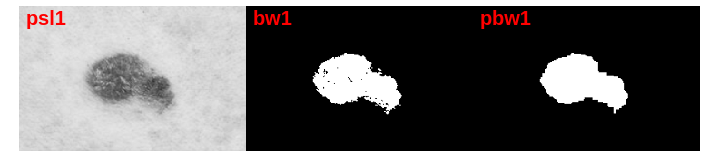

f1 = imread("psl1_gray.png");
f2 = imread("psl2_gray.png");
f3 = imread("psl3_gray.png");

th1 = graythresh(f1);
th2 = graythresh(f2);
th3 = graythresh(f3);

bw1 = 1 - imbinarize(f1, th1);
bw2 = 1 - imbinarize(f2, th2);
bw3 = 1 - imbinarize(f3, th3);

pbw1 = prettify(bw1);   
pbw2 = prettify(bw2);
pbw3 = prettify(bw3);

figure, montage({f1, bw1, pbw1}, "Size", [1 3])
text(30, 55, "psl1", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(1030, 55, "bw1", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(2030, 55, "pbw1", "FontSize", 15, "Color", "red", "FontWeight", "bold")

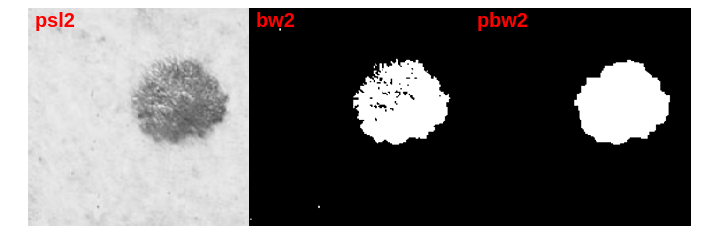


figure, montage({f2, bw2, pbw2}, "Size", [1 3])
text(30, 55, "psl2", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(1030, 55, "bw2", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(2030, 55, "pbw2", "FontSize", 15, "Color", "red", "FontWeight", "bold")

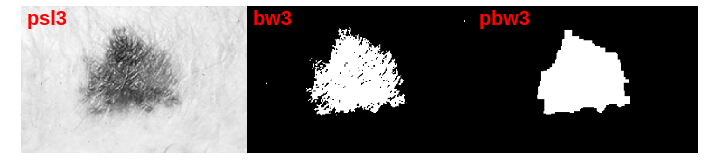


figure, montage({f3, bw3, pbw3}, "Size", [1 3])
text(30, 55, "psl3", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(1030, 55, "bw3", "FontSize", 15, "Color", "red", "FontWeight", "bold")
text(2030, 55, "pbw3", "FontSize", 15, "Color", "red", "FontWeight", "bold")

## Function

function pbw = prettify(bw)

ose = strel("square", 3);
o = imopen(bw, ose);

cse = strel("square", 10);
c = imclose(o, cse);

pbw = c;

end